# Newton-Verfahren mit numerischer Differentiation

Wir betrachten das Gravitationsbeispiel aus Abschnitt 5.1:

    
$$f_1(x,y)  =  \sum_{i=1}^3 \frac{m_i(x_i-x)}{((x-x_i)^2+(y-y_i)^2)^{3/2}} =0$$


    
$$f_2(x,y)  =  \sum_{i=1}^3 \frac{m_i(y_i-y)}{((x-x_i)^2+(y-y_i)^2)^{3/2}} =0,$$


mit Parameterwerten $m_1=10,~m_2=13,~m_3=6, ~(x_1,y_1)=(-3,0),~(x_2,y_2)=(2,0),~(x_3,y_3)=(0,4).$ 

Zur Bestimmung einer Annäherung einer Nullstelle verwenden wir das Newton-Verfahren mit Startwert $(x^0,y^0)=(-0.8,0.2).$

Die Jacobi-Matrix wird über numerische Differentiation mit Schrittweite $h=10^{-m}$ bestimmt. Der Wert für $m$ wird gewählt:

m=10;

Es werden 9 Iterationsschritte des Newton-Verfahrens durchgeführt und die Werte

       ${\rm Normf}(k):=\|f(x^k,y^k)\|_2$,  $k=0,\ldots,9$,

werden bestimmt. Der Wert ${\rm Normf}(4)$ wird ausgegeben und die Werte ${\rm Normf}(k)$, $k=0,\ldots,9$,  werden in einer Grafik gezeigt.

# Aktivität:

Variieren Sie den $m$-Wert, z.B. $m \in \{2,3,4,5,9,12,13,15\}$, und erklären Sie, weshalb die Ergebnisse für $5 \leq m \leq 12$ besser  sind als die für $m \leq 3$ oder $m \geq 13$.

xold= [-0.8 0.2]'; % Startwert
b= -F(xold);
Normf= zeros(10,1);
Normf(1)= norm(b);
h=10^(-m)

h =    1.0000e-10


for k=1:9
    % Newton-Schritt
    A= DF(xold,h);
    s= A\b;
    xnew= xold+s;
    b= -F(xnew);
    Normf(k+1)= norm(b);
    xold= xnew;
end;
fprintf('\nNorm des Funktionswertes nach 4 Iterationen, Normf(4): \n');


Norm des Funktionswertes nach 4 Iterationen, Normf(4): 


Normf(5) % Vektorindex beginnt bei 1, obwohl k bei 0 beginnt

ans =    2.7894e-16


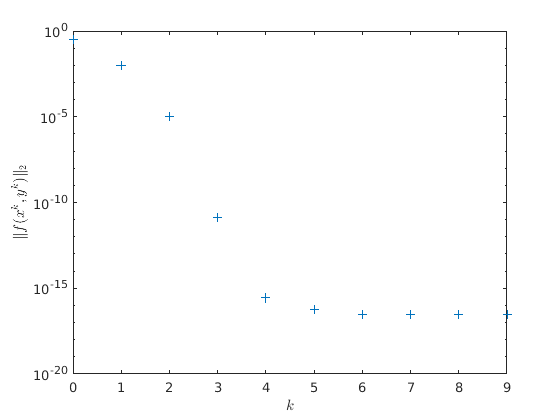

semilogy([0:9],Normf,'+'); 
xlabel('$k$','Interpreter','latex'); ylabel('$\|f(x^k,y^k)\|_2$','Interpreter','latex');

function [DFout]=DF(x,h)
 DFout=zeros(2,2);
 DFout(:,1)=1/h*(F(x+h*[1 0]')-F(x));
 DFout(:,2)=1/h*(F(x+h*[0 1]')-F(x));
end

function [Fout]=F(x)
  m1=10; 
  m2=13;
  m3=6;
  M1=[-3 0];
  M2=[2 0];
  M3=[0 4];
  Fout=zeros(2,1);
  Fout(1)=m1*(M1(1)-x(1))*((M1(1)-x(1))^2+(M1(2)-x(2))^2)^(-1.5)+m2*(M2(1)-x(1))*((M2(1)-x(1))^2+(M2(2)-x(2))^2)^(-1.5)+m3*(M3(1)-x(1))*((M3(1)-x(1))^2+(M3(2)-x(2))^2)^(-1.5);
  Fout(2)=m1*(M1(2)-x(2))*((M1(1)-x(1))^2+(M1(2)-x(2))^2)^(-1.5)+m2*(M2(2)-x(2))*((M2(1)-x(1))^2+(M2(2)-x(2))^2)^(-1.5)+m3*(M3(2)-x(2))*((M3(1)-x(1))^2+(M3(2)-x(2))^2)^(-1.5);
end